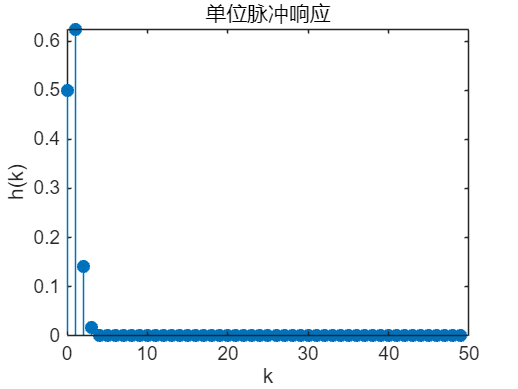

%Q1
%(1)
num = [1,1];
den = [2,-0.5,0.06];
n = 0:49;
h = impz(num, den, n);
figure
stem(n, h, 'filled');
xlabel('k');
ylabel('h(k)');
title('单位脉冲响应');

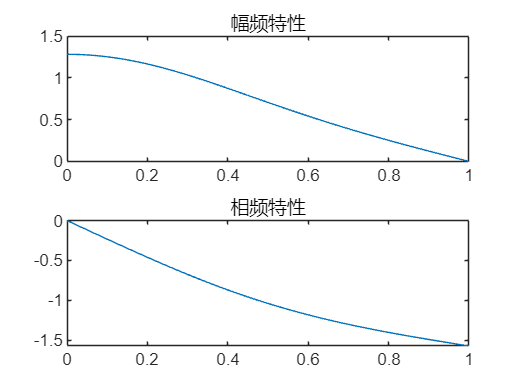


%(2)
[H, w] = freqz(num, den);
figure;
subplot(2,1,1);
plot(w/pi, abs(H));
title('幅频特性');

subplot(2,1,2);
plot(w/pi, angle(H));
title('相频特性');

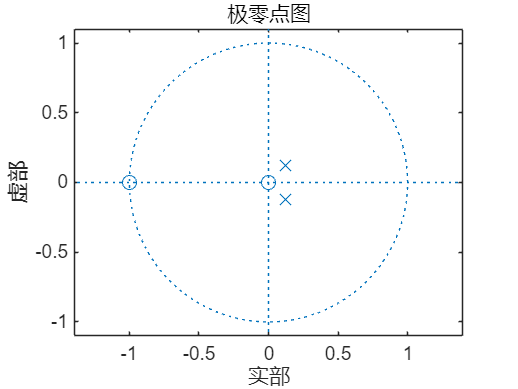

%由图可知，是低通滤波器

%(3)
figure;
zplane(num,den);
title('极零点图')

%由图可知，极点都在单位圆内部，稳定

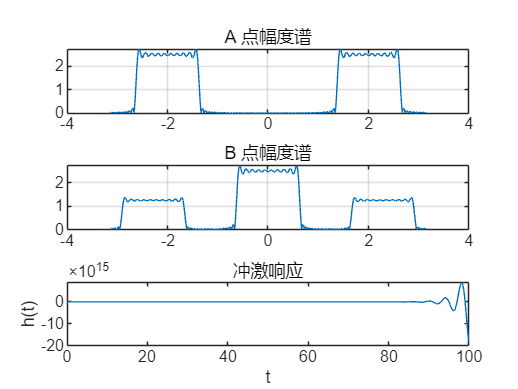

%Q2
%（1）
num = 1;
den = [1,0,2,2];
t = 0:0.1:100;
y = impulse(num,den,t);
plot(t,y);
xlabel('t');
ylabel('h(t)');
title('冲激响应');


poles = roots(den);        
pole_real = real(poles);  
if all(pole_real < 0)
    disp('系统稳定');
else
    disp('系统不稳定');
end

系统不稳定


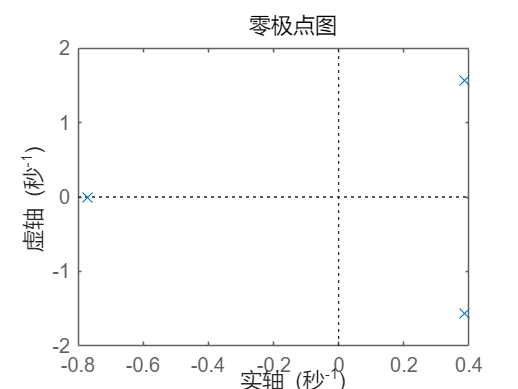

%所有极点实部小于零，系统才稳定

%（2）
figure
pzmap(num,den)


poles = roots(den);        
pole_real = real(poles);  
if all(pole_real < 0)
    disp('系统稳定');
else
    disp('系统不稳定');
end

系统不稳定


%所有极点实部小于零，系统才稳定

%(3)
disp('罗斯 - 霍维茨阵列：');

罗斯 - 霍维茨阵列：


disp('s^3:  1    2');

s^3:  1    2


disp('s^2:  0(e)    2  ');

s^2:  0(e)    2  


disp('s^1:  -2/e  0');

s^1:  -2/e  0


disp('s^0:  2    0');

s^0:  2    0


disp('第一列符号变了两次，不稳定')

第一列符号变了两次，不稳定


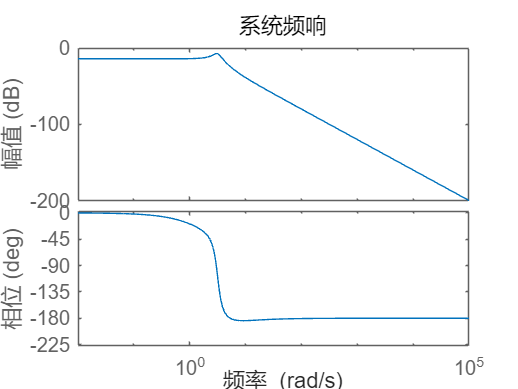

%Q3
%(1)
num = [1, 4];         
den = [1, 3, 12, 20]; 
sys = tf(num,den);

y0 = 1;
dy0 = 0;
ddy0 = -6;

t = 0:0.1:5;
x = sin(0.5 * pi * t);

figure;
h = bodeplot(sys, {10^-2, 10^5});
title('系统频响');


%(2)
[A,B,C,D] = tf2ss(num,den);
sys_ss = ss(A,B,C,D);
x0 = 0;
dx0 = 0.5 * pi;


M = [C; C*A; C*A^2];
b = [y0; 
     dy0 - C*B*x0; 
     ddy0 - C*A*B*x0 - C*B*dx0];

z0 = M \ b;


disp('状态变量的初始值');

状态变量的初始值



z0

z0 =    -0.3636
    0.0909
    0.2273


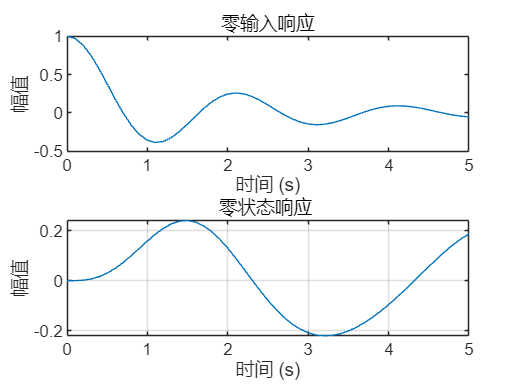


%(3)
figure
subplot(2,1,1);
y_zi = initial(sys_ss, z0, t);
plot(t, y_zi)
xlabel('时间 (s)');
ylabel('幅值');
title('零输入响应');

subplot(2, 1, 2);
y_zs = lsim(sys_ss, x, t, [0; 0; 0]);
plot(t, y_zs);
title('零状态响应 ');
xlabel('时间 (s)');
ylabel('幅值');
grid on;

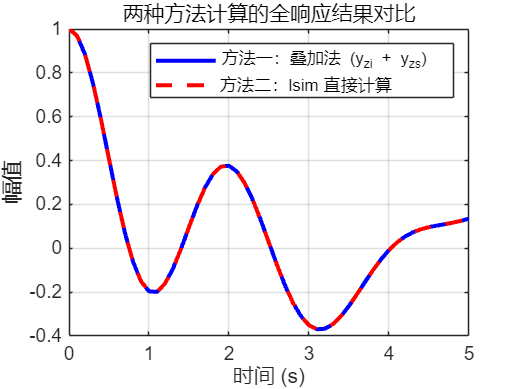


%(4)
y_total1 = y_zs+y_zi;
y_total2 = lsim(sys_ss,x,t,z0);
figure
plot(t, y_total1, 'b-', 'LineWidth', 2); 
hold on;
plot(t, y_total2, 'r--', 'LineWidth', 2); 
title('两种方法计算的全响应结果对比');
xlabel('时间 (s)');
ylabel('幅值');
grid on;
legend('方法一：叠加法 (y_{zi} + y_{zs})', '方法二：lsim 直接计算');
hold off;

%显然相等

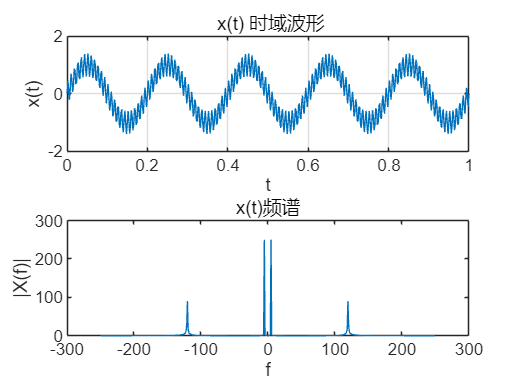

%Q4
%(1)
Ts = 0.002;
f1 = 5;
f2 = 120;
Fs = 1/Ts;
t = 0:Ts:1;
L = length(t);

x = sin(2*pi*f1*t) + 0.4*sin(2*pi*f2*t);
h = [0.008, 0.02, 0.06, 0.12, 0.17, 0.2, 0.17, 0.12, 0.06, 0.02, 0.008];

figure
subplot(2, 1, 1);
plot(t, x);
title(' x(t) 时域波形');
xlabel('t');
ylabel('x(t)');
grid on;

X = fftshift(fft(x));
f = (-L/2:L/2-1)*(Fs/L);
subplot(2,1,2);
plot(f,abs(X));
xlabel('f');
ylabel('|X(f)|');
title('x(t)频谱');


%(2)
y = conv(x,h,'same')

y =     0.0958    0.1244    0.1488    0.1868    0.2393    0.2950    0.3501    0.4026    0.4565    0.5101    0.5590    0.6037    0.6486    0.6932    0.7328    0.7669    0.8000    0.8327    0.8605    0.8820    0.9011    0.9199    0.9342    0.9416    0.9456    0.9493    0.9492    0.9420    0.9307    0.9190    0.9045    0.8833    0.8573    0.8310    0.8030    0.7690    0.7301    0.6908    0.6510    0.6065    0.5569    0.5071    0.4582    0.4058    0.3488    0.2917    0.2365    0.1796    0.1188    0.0578


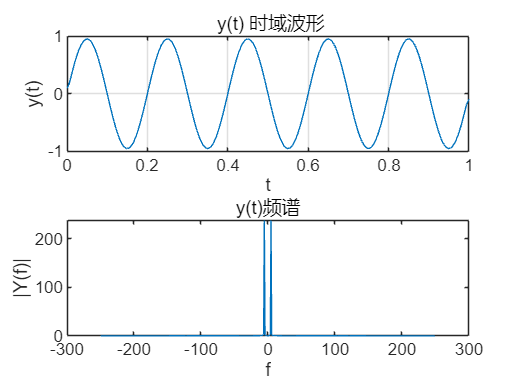

figure
subplot(2, 1, 1);
plot(t, y);
title(' y(t) 时域波形');
xlabel('t');
ylabel('y(t)');
grid on;

Y = fftshift(fft(y));
f = (-L/2:L/2-1)*(Fs/L);
subplot(2,1,2);
plot(f,abs(Y));
xlabel('f');
ylabel('|Y(f)|');
title('y(t)频谱');


%(3)
%f2的频谱没通过只留下了f1，所以h是个低通滤波器

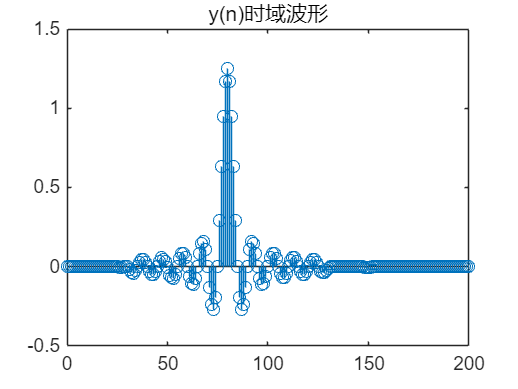

%Q5
%（1）
n = 0:100;
x = sinc(0.2*(n-50)).*cos(2*n);
s = cos(2*n);
h = sinc(0.4*(n-30));
y = conv(x.*s,h);
L1 = length(n);

n1 = 0:200;
figure;
stem(n1,y);
title('y(n)时域波形');

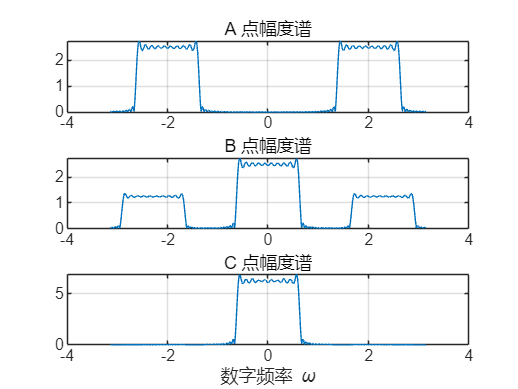


%(2)
NFFT = 1024;
w = linspace(-pi,pi,NFFT);
A = abs(fftshift(fft(x,NFFT)));
B = abs(fftshift(fft(x.*s,NFFT)));
C = abs(fftshift(fft(y,NFFT)));

subplot(3, 1, 1);
plot(w, A);
title('A 点幅度谱');
grid on;

subplot(3, 1, 2);
plot(w, B);
title('B 点幅度谱');
grid on;

subplot(3, 1, 3);
plot(w, C);
title('C 点幅度谱');
grid on;
%A到B是经过cos（2n）解调，恢复成门函数和另外两个高频波，B到C是通过低通滤波器把门函数提取出来还原